# Hands-On: C2D with Sampler & Hold - First Experiment

## First Scenario: Discretising  an LTI System with only Real Eigenvalues

Let's consider the continuous-time LTI system


$$\left\{ \begin{array}{lcl}
			\dot{x}(t) &=& \left[ \begin{array}{cc} 
												0 & 1\\0 & -1 
											\end{array} \right] \cdot x(t) + \left[\begin{array}{c} 0 \\ 10  \end{array} \right] \cdot u(t) \\[0.5em] \\
			y(t) &=&\left[ \begin{array}{cc}
									 1 & 0
									\end{array}  \right] \cdot x(t)
			\end{array} \right.$$


What happens, if you choose a few different sampling periods $\Delta_1\,,\; \Delta_2\,, \ldots \Delta_{10}$ such that

 
$$\Delta_i \in \left[ \frac{1}{1000} \,,\; 10 \right] \quad \forall i = 1\,,\;2\,, \ldots 10$$


and then compute the discrete-time description of the considered LTI system?

Write a piece of code, allowing:

-  To select a set of sample periods, as specified above;

-  To compute, for each selected sampling time, the discrete time representation of the given continuous time LTI system;

-  To plot the eigenvalues of the discrete-time description of the given LTI system;

- To compare the free state movement of the continuous time system and the free state movement of each discrete time description, starting from the initial state $x_{0} = \left[ \begin{array}{cc} -2 & +3 \end{array} \right]^{T}$


% write here the code solving the problem 

matA = [ 0 1; 0 -1 ];
matB = [ 0; 10 ];
matC = [ 1 0 ];
matD = 0;

Deltas = linspace(1/1000,10,10);

sysC = ss(matA,matB,matC,matD);

for whichOne = 1:size(Deltas, 2)
    sysD = c2d(sysC,Deltas(whichOne));
    
    % plot the eigenvalues of the discrete-time description of the given LTI system;
    
    disp(eig(sysD.A)); % we use the matrix A to compare the eigen values corresponding to the free state moevement
    
    % compare the free state movement of the continuous time system and the free state movement of each discrete time description, starting from the initial state 
    x_0 = [-2 3]';
    
    t = 0:Deltas(whichOne):10;
    U = zeros(1, size(t, 2));
    lsim(sysD, U, t, x_0);
    grid on;
end

- What could be the behavior of the discrete-time description eigenvalues, when increasing or decreasing the sampling frequency $f_s = 1/ \Delta$ ? 

- Did you find any difference between the free movement of the state of the original continuous-time system and the discrete-time representations you obtained?

- Finally, analysing the results, try to figure out a good choice for $\Omega_{\text{B}}$, or equivalently for $f_{\text{B}}$ , in order to obtain a proficient discrete-time description of the given LTI system.

Now suppose to feed the continuous time system with the input 


$$u(t) = t e^{-4t}\sin \left(2 \pi \bar{f}t - \frac{pi}{6}\right)\cdot 1(t) \quad \bar{f} = 2.0\;\text{[Hz]}$$


and assume to sample also the input signal, beside the state and the output variables.

- Is the previously chosen sampling period still a good choice? Or do you have to select a different value?

- What if $\bar{f} = 200.0 \; \text{[Hz]}$?

- Write a few lines of code, implementing a comparison of the state and output movements, starting from the assigned initial state $x_0$ and the predefined input, for the continuous-time system and the discrete-time representation obtained, discretizing the system equations according to the chosen sampling period.

    1.0000
    0.9990



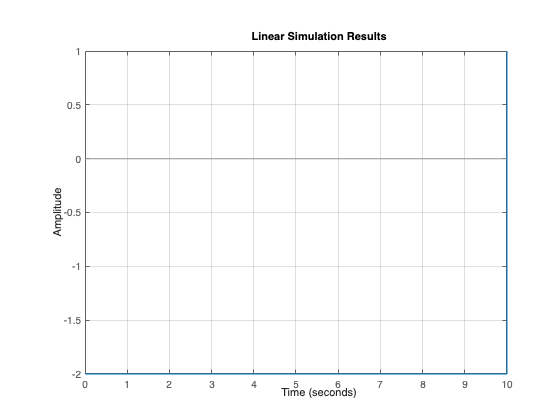


% write here the code solving the problem 

f = 200;

for whichOne = 1:size(Deltas, 2)
    sysD = c2d(sysC,Deltas(whichOne));
    
    % plot the eigenvalues of the discrete-time description of the given LTI system;
    
    disp(eig(sysD.A)); % we use the matrix A to compare the eigen values corresponding to the free state moevement
    
    % compare the free state movement of the continuous time system and the free state movement of each discrete time description, starting from the initial state 
    x_0 = [-2 3]';
    
    t = 0:Deltas(whichOne):10;
    U = t.*e^(-4*t) .* sin(2*pi*f*t - pi/6) .* heaviside(t);
    lsim(sysD, U, t, x_0);
    grid on;
end

## Second Scenario: Discretising an LTI System with Complex Eigenvalues

Consider now the continuous-time LTI system


$$\left\{ \begin{array}{lcl}
			\dot{x}(t) &=& \left[ \begin{array}{cc} 
												1 & 2\\-2 & 1 
											\end{array} \right] \cdot x(t) + \left[\begin{array}{c} 0 \\ 10  \end{array} \right] \cdot u(t) \\[0.5em] \\
			y(t) &=&\left[ \begin{array}{cc}
									 1 & 0
									\end{array}  \right] \cdot x(t)
			\end{array} \right.$$


and repeat the same computation steps. What is your finding?


% write here the code solving the problem 


Do you find any significant difference by comparing the two cases? 